# SSP-SDIRK4

syms zeta;
assume(zeta, "real");
A = [zeta, 0, 0
    0.5 - zeta, zeta, 0
    2 * zeta, 1 - 4 * zeta, zeta]

$$A = \left(\begin{array}{ccc} \zeta & 0 & 0\\ \frac{1}{2}-\zeta & \zeta & 0\\ 2\,\zeta & 1-4\,\zeta & \zeta \end{array}\right)$$

sqr = @(v) v.^2;
B = [ 1. / (6 * sqr(2 * zeta - 1))
    (4 * sqr(zeta) - 4 * zeta + 2. / 3.) / sqr(2 * zeta - 1)
    1. / (6 * sqr(2 * zeta - 1))]'

$$B = \left(\begin{array}{ccc} \frac{1}{6\,{\left(2\,\zeta -1\right)}^{2}} & \frac{4\,\zeta^{2}-4\,\zeta +\frac{2}{3}}{{\left(2\,\zeta -1\right)}^{2}} & \frac{1}{6\,{\left(2\,\zeta -1\right)}^{2}} \end{array}\right)$$

C = [zeta, 0.5, 1 - zeta]'

$$C = \left(\begin{array}{c} \zeta \\ \frac{1}{2}\\ 1-\zeta \end{array}\right)$$


syms lambda dt z% y' = lambda y
syms y0 y
ylast = y0;
dydt = sym("dydt", [3,1]);
for iB = 1:3
    eq = (y0 - y)/dt + A(iB,1:iB-1) * dydt(1:iB-1) + A(iB, iB) * y * lambda;
    ycur = solve(eq, y);
    dydt(iB) = ycur * lambda;
end
y1 = simplify(expand(y0 + B * dydt * dt))

$$y1 = \frac{y_{0}\,\left(24\,{\mathrm{dt}}^{3}\,\lambda^{3}\,\zeta^{4}-60\,{\mathrm{dt}}^{3}\,\lambda^{3}\,\zeta^{3}+36\,{\mathrm{dt}}^{3}\,\lambda^{3}\,\zeta^{2}-10\,{\mathrm{dt}}^{3}\,\lambda^{3}\,\zeta +{\mathrm{dt}}^{3}\,\lambda^{3}-72\,{\mathrm{dt}}^{2}\,\lambda^{2}\,\zeta^{3}+108\,{\mathrm{dt}}^{2}\,\lambda^{2}\,\zeta^{2}-48\,{\mathrm{dt}}^{2}\,\lambda^{2}\,\zeta +6\,{\mathrm{dt}}^{2}\,\lambda^{2}+72\,\mathrm{dt}\,\lambda \,\zeta^{2}-60\,\mathrm{dt}\,\lambda \,\zeta +12\,\mathrm{dt}\,\lambda -24\,\zeta +12\right)}{12\,{\left(\mathrm{dt}\,\lambda \,\zeta -1\right)}^{3}\,\left(2\,\zeta -1\right)}$$

K = subs(y1/y0, lambda, z/dt)

$$K = \frac{24\,z^{3}\,\zeta^{4}-60\,z^{3}\,\zeta^{3}+36\,z^{3}\,\zeta^{2}-10\,z^{3}\,\zeta +z^{3}-72\,z^{2}\,\zeta^{3}+108\,z^{2}\,\zeta^{2}-48\,z^{2}\,\zeta +6\,z^{2}+72\,z\,\zeta^{2}-60\,z\,\zeta +12\,z-24\,\zeta +12}{12\,\left(2\,\zeta -1\right)\,{\left(z\,\zeta -1\right)}^{3}}$$

fK = matlabFunction(symfun(K, [z,zeta]));

## Numeric draw:

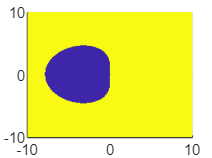


seeRang = 10;
nSee = 201;
reals = linspace(-seeRang,seeRang,nSee);
imags = linspace(-seeRang,seeRang,nSee);
[realm, imagm] = meshgrid(reals,imags);
zsamp = realm + 1i * imagm;
Ksamp = fK(zsamp,0.1);

surf(realm,imagm, double(abs(Ksamp)>1), "LineStyle","none");
view([0,90]);

## ESDIRK4


A = [0, 0, 0, 0, 0, 0
    0.25, 0.25, 0, 0, 0, 0
    0.137776, -0.055776, 0.25, 0, 0, 0
    0.1446368660269822, -0.2239319076133447, 0.4492950415863626, 0.25, 0, 0
    0.09825878328356477, -0.5915442428196704, 0.8101210205756877, 0.283164405707806, 0.25, 0
    0.1579162951616714, 0, 0.1867589405240008, 0.6805652953093346, -0.2752405309950067, 0.25];
B = A(end,:);
C = [0, 0.5, 0.332, 0.62, 0.849999966747388, 1];

syms lambda dt z% y' = lambda y
assume(dt>0);
syms y0 y
ylast = y0;
dydt = sym("dydt", [6,1]);
for iB = 1:6
    eq = (y0 - y)/dt + A(iB,1:iB-1) * dydt(1:iB-1) + A(iB, iB) * y * lambda;
    ycur = solve(eq, y);
    dydt(iB) = ycur * lambda;
end
% y1 = simplify(expand(y0 + B * dydt * dt))
y1 = simplify(expand(ycur))

$$y1 = -\frac{y_{0}\,\left(36729986694336113038443840602351641\,{\mathrm{dt}}^{5}\,\lambda^{5}+3023721252900880424919364323065319507896116\,{\mathrm{dt}}^{4}\,\lambda^{4}+3455680184884617541099124763360986857326000\,{\mathrm{dt}}^{3}\,\lambda^{3}-41468174412351523453170488818548623737000000\,{\mathrm{dt}}^{2}\,\lambda^{2}-82936354897280730290344309120099680256000000\,\mathrm{dt}\,\lambda +331745419589123060775253513576478932992000000\right)}{323970136317502989038333509352030208000000\,{\left(\mathrm{dt}\,\lambda -4\right)}^{5}}$$

K = subs(y1/y0, lambda, z/dt)

$$K = -\frac{36729986694336113038443840602351641\,z^{5}+3023721252900880424919364323065319507896116\,z^{4}+3455680184884617541099124763360986857326000\,z^{3}-41468174412351523453170488818548623737000000\,z^{2}-82936354897280730290344309120099680256000000\,z+331745419589123060775253513576478932992000000}{323970136317502989038333509352030208000000\,{\left(z-4\right)}^{5}}$$

fK = matlabFunction(symfun(K, [z]));



## Numeric draw

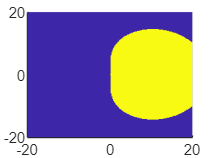

seeRang = 20;
nSee = 201;
reals = linspace(-seeRang,seeRang,nSee);
imags = linspace(-seeRang,seeRang,nSee);
[realm, imagm] = meshgrid(reals,imags);
zsamp = realm + 1i * imagm;
Ksamp = fK(zsamp);

surf(realm,imagm, double(abs(Ksamp)>1), "LineStyle","none");
view([0,90]);